# MCIR Bode Plot Comparison

Start by creating one circuit and modifying a copy.

import MCIR.*

% Create the first circuit
CIR1 = Circuit("Original");
CIR1 <= "Vin 1 0 AC(1)"
CIR1 <= "R1 1 2 10k"
CIR1 <= "C1 2 0 100n"

% Make a copy of it - note that copy() must be used as it is a handle class.
CIR2 = CIR1.copy;
CIR2.name = "Modified";
CIR2.alter("C1", "47n")

CIR1.list

* Original

VIN 1 0 AC=1
R1 1 2 10k
C1 2 0 100n


CIR2.list

* Modified

VIN 1 0 AC=1
R1 1 2 10k
C1 2 0 47n


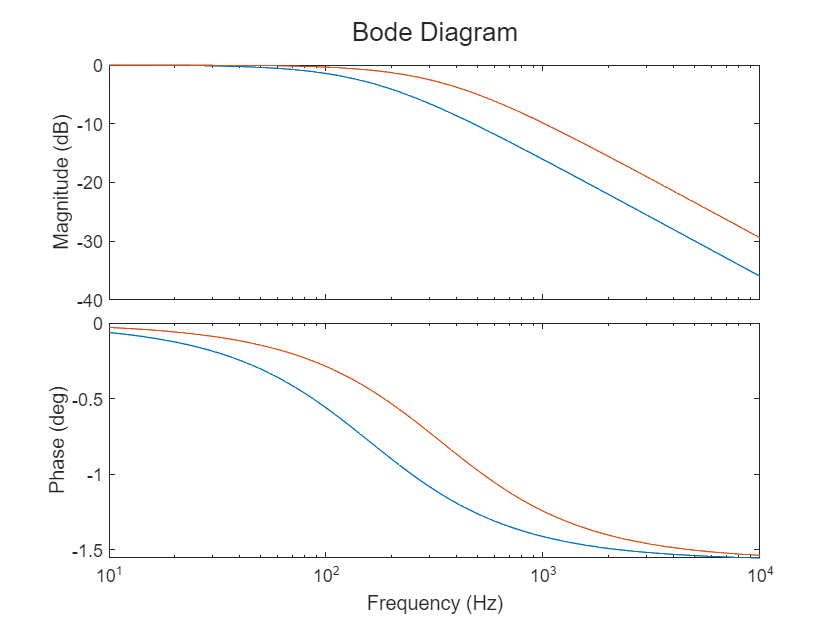

[H1,f] = CIR1.ac(10,10e3,50);
H2   = CIR2.ac(f);
bode_compare(f, H1, H2)